% Defining system matrices
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;

A = [0 1 0 0 0 0;
         0 0 -(m1*9.81)/M 0 -(m2*9.81)/M 0;
         0 0 0 1 0 0;
         0 0 -((M+m1)*9.81/(M*l1)) 0 -(m2*9.81)/(M*l1) 0;
         0 0 0 0 0 1;
         0 0 -(m1*9.81)/(M*l2) 0 -((M+m2)*9.81/(M*l2)) 0];


B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

Q = 100*eye(6);

R = 0.001

R = 1.0000e-03

K = lqr(A,B,Q,R);

D = 0;

rank_ctrb = rank(ctrb(A, B));
disp(rank_ctrb);

     6





C1 = [1 0 0 0 0 0];

C2 = [1 0 0 0 0 0;
      0 0 0 0 1 0];

C3 = [1 0 0 0 0 0;
      0 0 1 0 0 0;
      0 0 0 0 1 0];

Assume the desired poles for the luenberger observer, and calculate the observer gain for the three different outputs.

L_poles = [-1; -2; -3; -4; -5; -6];


L1 = place(A', C1', L_poles);
L2 = place(A', C2', L_poles);
L3 = place(A', C3', L_poles);

x_0 = [0;0;0.5;0;0.6;0];

Luenberger Observer for output x(t)

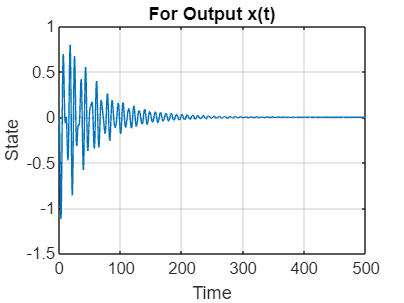

t_span = 0:0.01:500;
[t,x_L1] = ode45(@(t,x)nonlinear_luen(t,x,-K*x,L1,C1),t_span,x_0);
figure
plot(t,x_L1(:,1))
grid
xlabel('Time')
ylabel('State')
title('For Output x(t)')

Luenberger Observer for output {x(t),$\left.\theta 2\left(t\right)\right\rbrace$

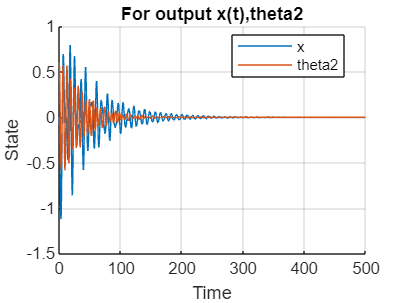

figure
hold on
[t,x_L2] = ode45(@(t,x)nonlinear_luen1(t,x,-K*x,L2',C2),t_span,x_0);
plot(t,x_L2(:,1))
plot(t,x_L2(:,5))
grid
xlabel('Time')
ylabel('State')
title('For output x(t),theta2')
legend({'x', 'theta2'},'Location','Best')
hold off

Luenberger Observer for output {x(t),$\left.\theta 1\left(t\right),\theta 2\left(t\right)\right\rbrace$

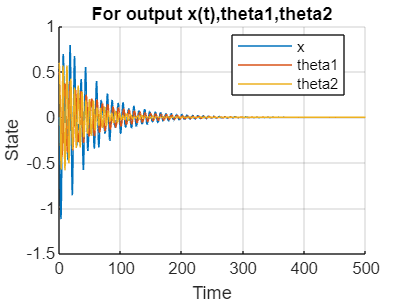

figure
hold on
[t,x_L3] = ode45(@(t,x)nonlinear_luen2(t,x,-K*x,L3',C3),t_span,x_0);
plot(t,x_L3(:,1))
plot(t,x_L3(:,3))
plot(t,x_L3(:,5))
grid
xlabel('Time')
ylabel('State')
title('For output x(t),theta1,theta2')
legend({'x', 'theta1', 'theta2'},'Location','Best')
hold off

function dx = nonlinear_luen(t,X,F,L,C)
dx = zeros(6,1);
% Declaring the values of system variables
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 9.81;
x = X(1);
x_d = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
obs = L*(x-C*X);
dx(1) = x_d + obs(1);
dx(2) = (F-((m1*sin(theta1)*cos(theta1))+(m2*sin(theta2)*cos(theta2)))*g - (l1*m1*(dx(3)^2)*sin(theta1)) - (l2*m2*(dx(5)^2)*sin(theta2)))/(m1+m2+M-(m1*(cos(theta1)^2))-(m2*(cos(theta2)^2)))+obs(2);
dx(3) = theta1_d+obs(3);
dx(4) = ((cos(theta1)*dx(2)-g*sin(theta1))/l1) + obs(4);
dx(5) = theta2_d + obs(5);
dx(6) = (cos(theta2)*dx(2)-g*sin(theta2))/l2 + obs(6);
end


function dx = nonlinear_luen1(t,X,F,L,C)
dx = zeros(6,1);
% Declaring the values of system variables
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 9.81;

x = X(1);
x_d = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
y3 = [x; theta2];
obs1 = L*(y3-C*X);
dx(1) = x_d + obs1(1);
dx(2) = (F-((m1*sin(theta1)*cos(theta1))+(m2*sin(theta2)*cos(theta2)))*g - (l1*m1*(dx(3)^2)*sin(theta1)) - (l2*m2*(dx(5)^2)*sin(theta2)))/(m1+m2+M-(m1*(cos(theta1)^2))-(m2*(cos(theta2)^2)))+obs1(2);
dx(3) = theta1_d+obs1(3);
dx(4) = ((cos(theta1)*dx(2)-g*sin(theta1))/l1) + obs1(4);
dx(5) = theta2_d + obs1(5);
dx(6) = (cos(theta2)*dx(2)-g*sin(theta2))/l2 + obs1(6);
end


function dx = nonlinear_luen2(t,X,F,L,C)
dx = zeros(6,1);
% Declaring the values of system variables
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 9.81;

x = X(1);
x_d = X(2);
theta1 = X(3);
theta1_d = X(4);
theta2 = X(5);
theta2_d = X(6);
y4 = [x; theta1; theta2];
obs2 = L*(y4-C*X);

dx(1) = x_d + obs2(1);
dx(2) = (F-((m1*sin(theta1)*cos(theta1))+(m2*sin(theta2)*cos(theta2)))*g - (l1*m1*(dx(3)^2)*sin(theta1)) - (l2*m2*(dx(5)^2)*sin(theta2)))/(m1+m2+M-(m1*(cos(theta1)^2))-(m2*(cos(theta2)^2)))+obs2(2);
dx(3) = theta1_d+obs2(3);
dx(4) = ((cos(theta1)*dx(2)-g*sin(theta1))/l1) + obs2(4);
dx(5) = theta2_d + obs2(5);
dx(6) = (cos(theta2)*dx(2)-g*sin(theta2))/l2 + obs2(6);
end
